# Model simluation for producing apparent sunk costs from drift to bound model

Code to generate Figure in Ott et al. (2021).

PM*, TO*, TSG and AK 

*equal contribution

[paul_masset@fas.harvard.edu](mailto:paul_masset@fas.harvard.edu)  [torbenott@wustl.edu](mailto:torbenott@wustl.edu)  [kepecs@wustl.edu](mailto:kepecs@wustl.edu)

clear all
close all

% Parameters
nTrials = 1000000; % Number of trials for simulation
Threshold = 18; % Threshold for accepting an offer (one "restaurant")

NoiseChoice = 5; % Noise across trials
NoiseAcc = 3; % Noise across timepoints within trials

% Generate offer amounts
OfferAmount = randi(30, nTrials, 1); % Value of the offers on each trial

% Generate trials and behavioral outputs according to normative investment model for restaurant row/web surf task (Figure 2 and 3)
[Choices, Reward, Time, InitialWillingess, Willingness] = RestaurantDecisionModel(OfferAmount, Threshold, NoiseChoice, NoiseAcc);

% Define the wait time bins
AllTime = Choices == 1;
FiveSeconds = Choices == 1 & OfferAmount >= 5 & Time >= 5;
TenSeconds = Choices == 1 & OfferAmount >= 10 & Time >= 10;
FifteenSeconds = Choices == 1 & OfferAmount >= 15 & Time >= 15;
TwentySeconds = Choices == 1 & OfferAmount >= 20 & Time >= 20;
TwentyFiveSeconds = Choices == 1 & OfferAmount >= 25 & Time >= 25;

% Probability of choosing offer as a function of offer amount
TimeBins = 0.5:1:30.5;
[xp,yp,yerp] = PsychoC(OfferAmount, Choices, TimeBins);

% Apparent behavioral signatures of sunk cost sensitivity
[x,y,yer ]       = PsychoC(OfferAmount(AllTime == 1), Reward(AllTime == 1), TimeBins);
[x5,y5,yer5]     = PsychoC(OfferAmount(FiveSeconds == 1), Reward(FiveSeconds == 1), TimeBins);
[x10,y10,yer10]  = PsychoC(OfferAmount(TenSeconds == 1), Reward(TenSeconds == 1), TimeBins);
[x15,y15,yer15]  = PsychoC(OfferAmount(FifteenSeconds == 1), Reward(FifteenSeconds == 1), TimeBins);
[x20,y20,yer20]  = PsychoC(OfferAmount(TwentySeconds == 1), Reward(TwentySeconds == 1), TimeBins);
[x25,y25,yer25]  = PsychoC(OfferAmount(TwentyFiveSeconds == 1), Reward(TwentyFiveSeconds == 1), TimeBins);

yfit   = fit(x,y,'poly1');
yfit5  = fit(x5(6:end),y5(6:end),'poly1');
yfit10 = fit(x10(11:end),y10(11:end),'poly1');
yfit15 = fit(x15(16:end),y15(16:end),'poly1');
yfit20 = fit(x20(21:end),y20(21:end),'poly1');
yfit25 = fit(x25(26:end),y25(26:end),'poly1');

xplot=1:30;

for t=1:29
    AllTrials = Choices==1 & OfferAmount<=(31-t);
    TrialsSec = Choices==1 & OfferAmount>=t & Time>=t;
    
    [xat,yat,yerat ]= PsychoC(OfferAmount(AllTrials==1),Reward(AllTrials==1),TimeBins);
    [xts,yts,yerts] = PsychoC(OfferAmount(TrialsSec==1),Reward(TrialsSec==1),TimeBins);
    
    FitAll = fit([1:30-t+1]',yat(1:30-t+1),'poly1');
    FitSec = fit([1:30-t+1]',yts(t:30),'poly1');
    
    SlopeAll(t) = FitAll.p1;
    SlopeSec(t)= FitSec.p1;
end

% Initial Willingness-to-wait plot

[AllWill,awbin] = hist(InitialWillingess(AllTime==1),40);
[TwentyWill,twbin] = hist(InitialWillingess(TwentySeconds==1),awbin);

% Subsample trials to show in the psychometric
nsamples = 300;
SomeTrials = randperm(nTrials,nsamples); 

ChosenSamples = Choices(SomeTrials);
OfferSamples = OfferAmount(SomeTrials);
RewardSamples = Reward(SomeTrials);
nsamplesR = sum(RewardSamples==1);
nsamplesNR = sum(RewardSamples==0 & ChosenSamples==0);
nsamplesNRL = sum(RewardSamples==0 & ChosenSamples==1);

## Psychometric, initial willigness conditioning and temporal correlation (Figure 3A-C)

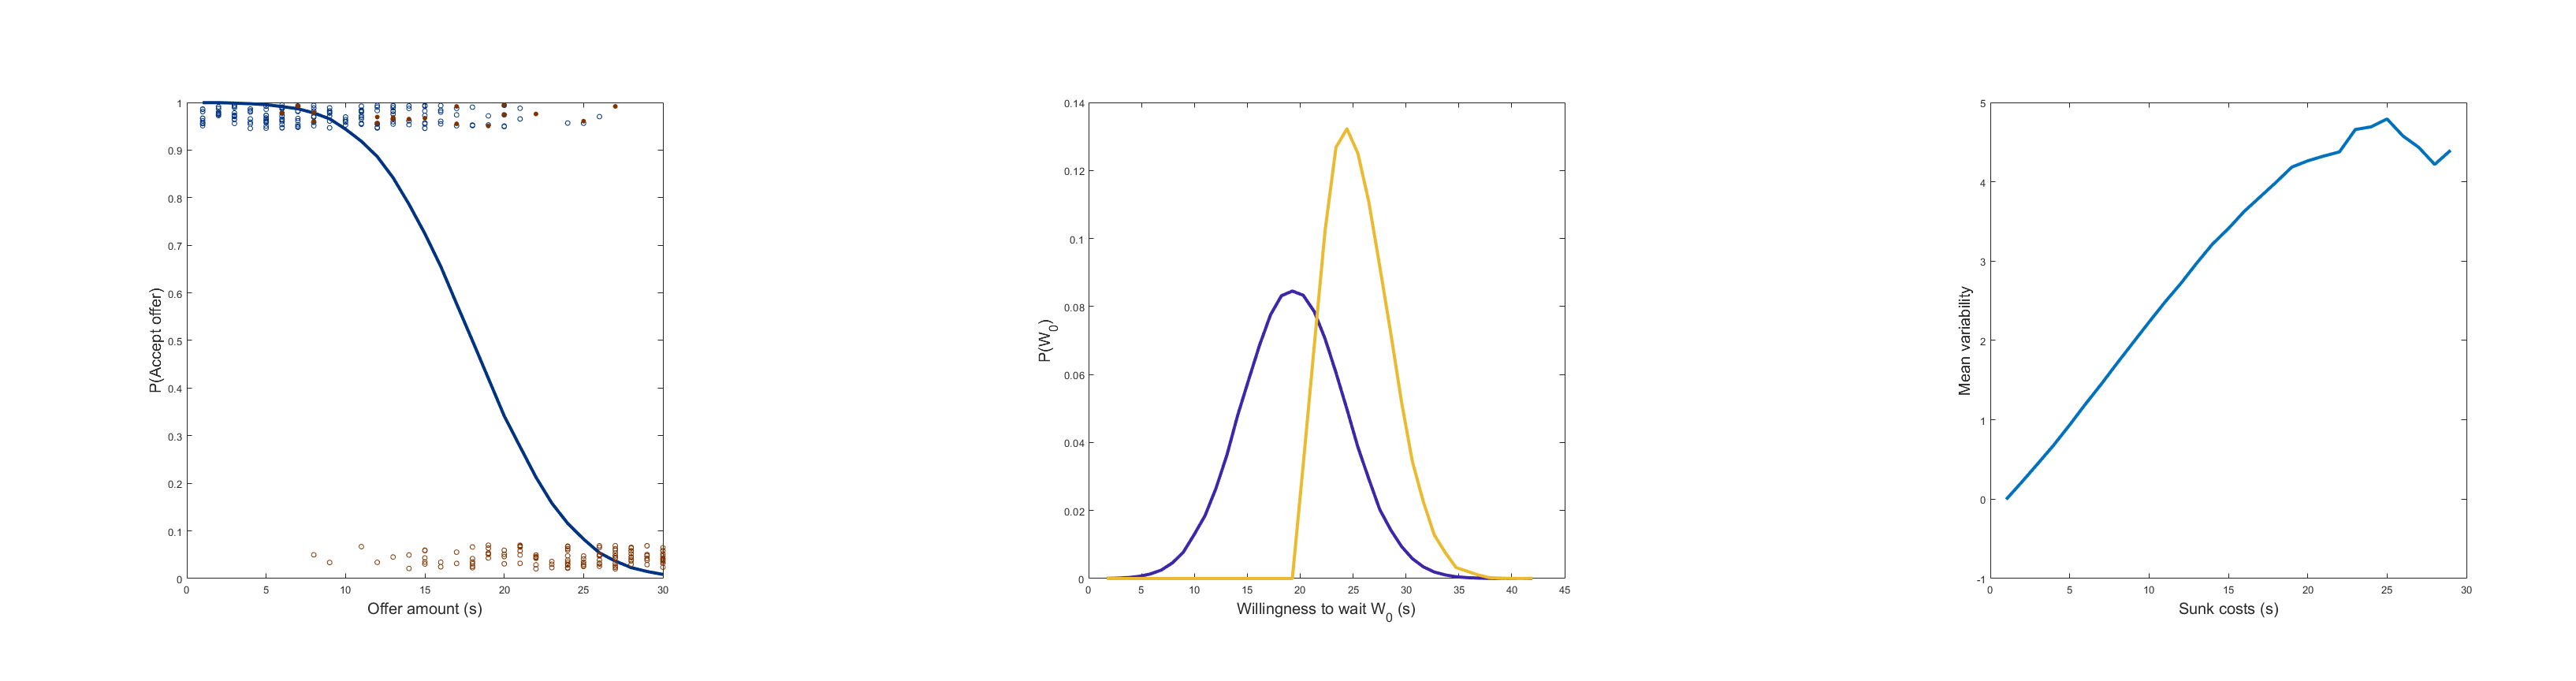

LabelFont=15;

F1=figure;
F1.Units='normalized';
F1.Position=[0 0 0.95 0.6];


map2=colormap('parula');
vec2=round(linspace(1,256,6));
map=colormap('parula');
vec=round(linspace(1,256,30));

pos1=[0.05 0.15 0.23 0.7];
pos2=[0.4 0.15 0.23 0.7];
pos3=[0.75 0.15 0.23 0.7];

subplot('Position', pos1)

plot(xp,yp,'LineWidth',3,'Color',[0 0.2 0.5]) 
hold on 
scatter(OfferSamples(RewardSamples==1),0.02 +0.925*ChosenSamples(RewardSamples==1)+0.05*rand(nsamplesR,1),20,[0 0.2 0.5])
scatter(OfferSamples(RewardSamples==0 & ChosenSamples==0),0.02 +0.925*ChosenSamples(RewardSamples==0 & ChosenSamples==0)+0.05*rand(nsamplesNR,1),20,[0.5 0.2 0])
scatter(OfferSamples(RewardSamples==0 & ChosenSamples==1),0.02 +0.925*ChosenSamples(RewardSamples==0 & ChosenSamples==1)+0.05*rand(nsamplesNRL,1),20,[0.5 0.2 0],'filled')

%ax=FormatAxis;
ylabel('P(Accept offer)','FontSize',LabelFont);
xlabel('Offer amount (s)','FontSize',LabelFont);
ax.YTick=[0 0.5 1];
ax.XTick=[0 15 30];
pbaspect([1 1 1])

subplot('Position',pos2)

plot(awbin,AllWill./nansum(AllWill),'LineWidth',3,'Color',map2(vec2(1),:))
hold on 
plot(awbin,TwentyWill./nansum(TwentyWill),'LineWidth',3,'Color',map2(vec2(5),:))
%ax=FormatAxis;
ylabel('P(W_0)','FontSize',LabelFont);
xlabel('Willingness to wait W_0 (s)','FontSize',LabelFont);
ax.YTick=0.1;
ax.XTick=[0 20 40];
ax.XLim=[0 40];
ax.YLim=[0 0.14];
pbaspect([1 1 1])

subplot('Position',pos3)

plot(nanmean(Willingness-InitialWillingess*ones(1,30),1),'LineWidth',3)
%ax=FormatAxis;
xlabel('Sunk costs (s)','FontSize',LabelFont)
ylabel('Mean variability','FontSize',LabelFont)
ax.YTick=[0 2 4];
ax.XTick=[0 15 30];
ax.YLim=[0 6];
pbaspect([1 1 1])

## Psychometric, initial willigness conditioning and temporal correlation (Figure 2F,G)

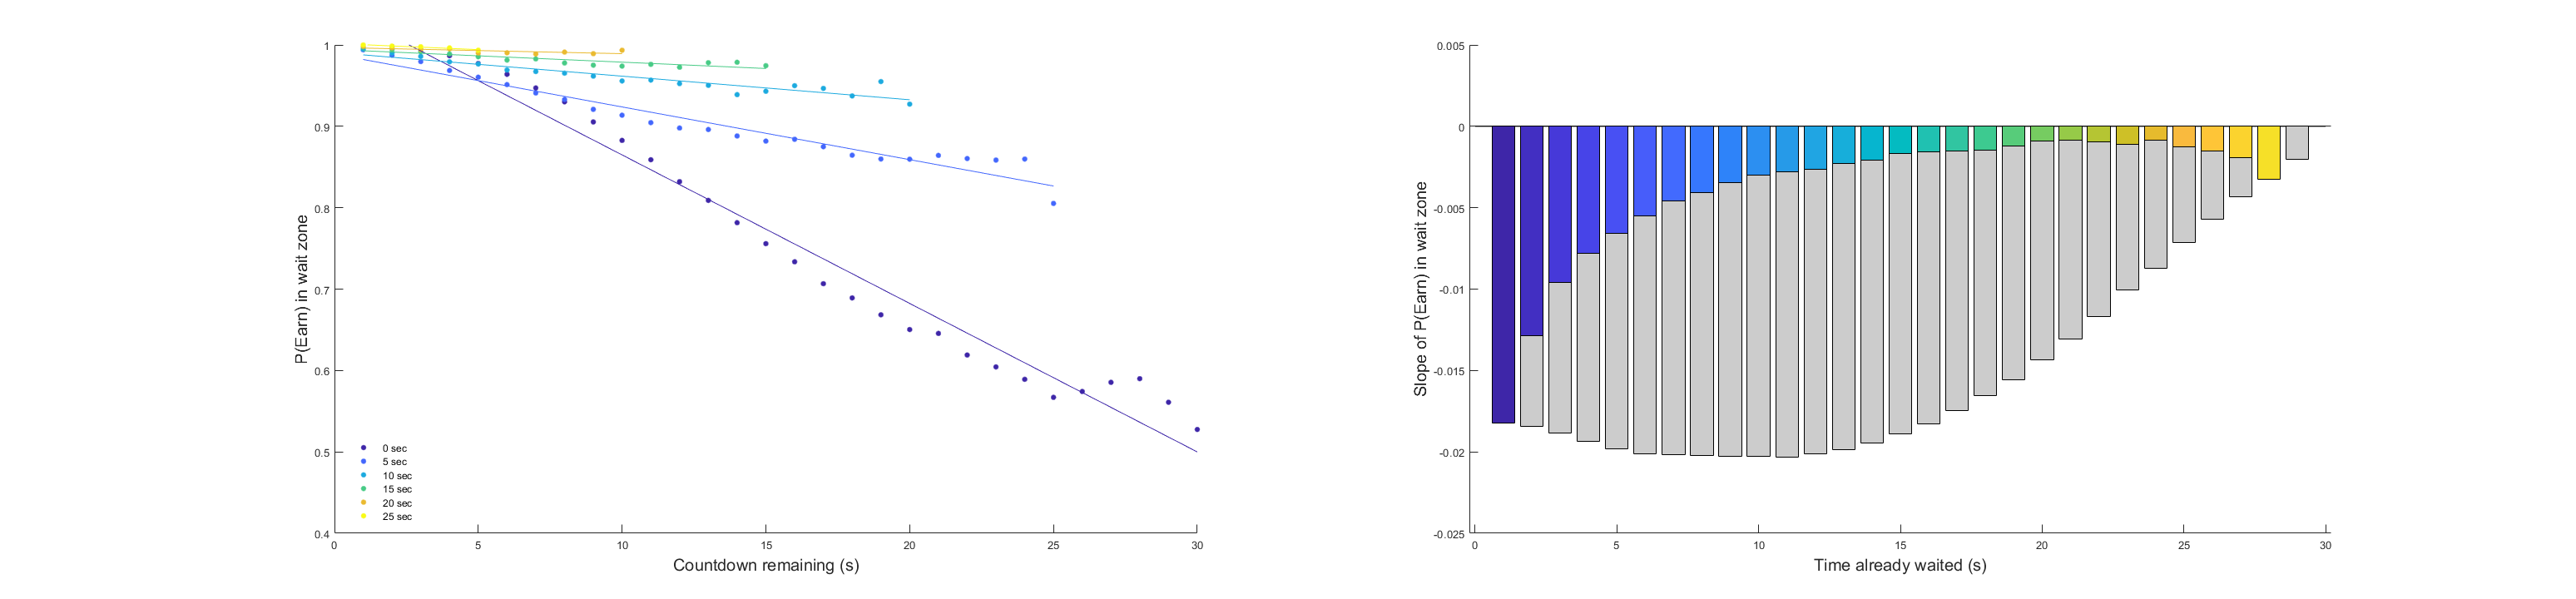

LabelFont=15;

F1=figure;
F1.Units='normalized';
F1.Position=[0 0 0.9 0.5];

subplot(121),hold on 
plot(y,'.','MarkerSize',15,'Color',map2(vec2(1),:))
plot(y5(6:end),'.','MarkerSize',15,'Color',map2(vec2(2),:))
plot(y10(11:end),'.','MarkerSize',15,'Color',map2(vec2(3),:))
plot(y15(16:end),'.','MarkerSize',15,'Color',map2(vec2(4),:))
plot(y20(21:end),'.','MarkerSize',15,'Color',map2(vec2(5),:))
plot(y25(26:end),'.','MarkerSize',15,'Color',map2(vec2(6),:))
plot(yfit(xplot),'Color',map2(vec2(1),:))
plot(yfit5(xplot(6:end)),'Color',map2(vec2(2),:))
plot(yfit10(xplot(11:end)),'Color',map2(vec2(3),:))
plot(yfit15(xplot(16:end)),'Color',map2(vec2(4),:))
plot(yfit20(xplot(21:end)),'Color',map2(vec2(5),:))
plot(yfit25(xplot(26:end)),'Color',map2(vec2(6),:))
%ax=FormatAxis;
ylabel('P(Earn) in wait zone','FontSize',LabelFont);
xlabel('Countdown remaining (s)','FontSize',LabelFont);
L1=legend('0 sec', '5 sec','10 sec','15 sec','20 sec','25 sec');
L1.Location='southwest';
L1.Box='off';

ylim([0.4 1])

subplot(122), hold on 

plot([0 30],[0 0],'k')

for t=1:29
    
    bar(t,SlopeAll(t),'FaceColor',[0.8 0.8 0.8]);
    bar(t,SlopeSec(t),'FaceColor',map(vec(t),:));
    
end
%ax=FormatAxis;
ylabel('Slope of P(Earn) in wait zone','FontSize',LabelFont);
xlabel('Time already waited (s)','FontSize',LabelFont);

ax.YTick=[ -0.02 0];
ax.YLim=[ -0.025 0.001];

**Augmented "restaurant row" task with revise offer**

% Generate trials and behavioral outputs according to  investment model for revise-restaurant row/web surf task (Figure 5)

ResetOffer = randi(30,nTrials,1); %amount of reset offer
ResetOfferTime = randi(30,nTrials,1); %timing of reset offer

%Rational agent%
NoiseChoice = 5;
NoiseAcc = 3;
SunkCostAgent = false; %normative model without considering sunk costs
[Choices, Reward, Time, InitialWillingess, Willingness, ResetTrial] = ReviseRestaurantDecisionModel(OfferAmount, ResetOffer, ResetOfferTime, Threshold, NoiseChoice, NoiseAcc, SunkCostAgent);

%Sunk cost sensitive agent%
NoiseChoice = 5;
NoiseAcc = 5; %Since W_t is generally higher due to sunk cost sensitivity, we need more noise to produce leaving decisions 
SunkCostAgent = true; % Agent who behaves sup-optimally by considering sunk costs
[ChoicesSunkCost, RewardSunkCost, TimeSunkCost, InitialWillingessSunkCost, WillingnessSunkCost, ResetTrialSunkCost] = ReviseRestaurantDecisionModel(OfferAmount, ResetOffer, ResetOfferTime, Threshold, NoiseChoice, NoiseAcc, SunkCostAgent);


**Sunk cost signatures of revise restaurant task (Figure 5CD)**

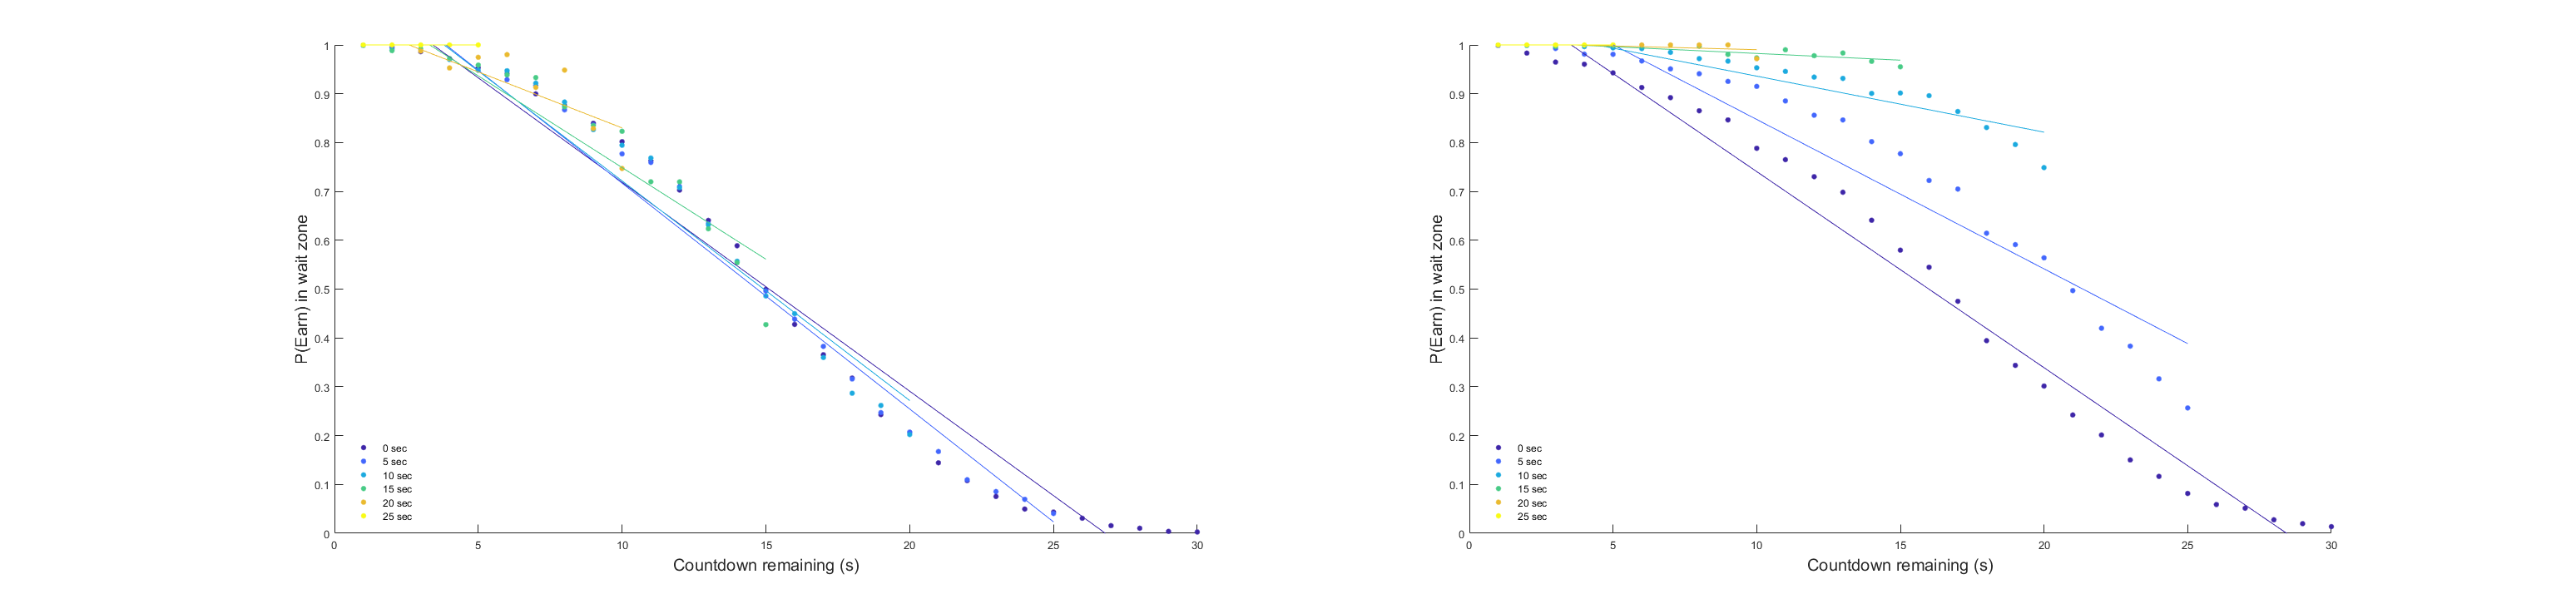

% Define the wait time bins (sunk cost bins)
AllTime = Choices == 1 & ResetTrial & ResetOfferTime < 5;
FiveSeconds = Choices == 1 & ResetOfferTime >= 5 & ResetOfferTime < 10 & ResetTrial;
TenSeconds = Choices == 1 & ResetOfferTime >= 10 & ResetOfferTime < 15 & ResetTrial;
FifteenSeconds = Choices == 1 & ResetOfferTime >= 15 & ResetOfferTime < 20 & ResetTrial;
TwentySeconds = Choices == 1 & ResetOfferTime >= 20 & ResetOfferTime < 25 & ResetTrial;
TwentyFiveSeconds = Choices == 1 & ResetOfferTime >= 25 & ResetTrial;

% Behavioral signatures of sunk cost sensitivity
TimeRevise = Time - ResetOfferTime; %time in revise offer (Time is time in trial)

for k = 1:30
    i0 = ResetOffer == k & Time>=0;
    i5 = ResetOffer == k & Time>=5;
    i10 = ResetOffer == k & Time>=10;
    i15 = ResetOffer == k & Time>=15;
    i20 = ResetOffer == k & Time>=20;
    i25 = ResetOffer == k & Time>=25;
    
    y(k)     = nanmean(Reward(AllTime  & i0));
    y5(k)    = nanmean(Reward(FiveSeconds  & i5));
    y10(k)   = nanmean(Reward(TenSeconds &  i10));
    y15(k)   = nanmean(Reward(FifteenSeconds &  i15));
    y20(k)   = nanmean(Reward(TwentySeconds &  i20));
    y25(k)   = nanmean(Reward(TwentyFiveSeconds &  i25));
end


x=1:30;x=x(:);y=y(:);
yfit   = fit(x,y,'poly1');
yfit5  = fit(x(1:end-5),y5(1:end-5),'poly1');
yfit10 = fit(x(1:end-10),y10(1:end-10),'poly1');
yfit15 = fit(x(1:end-15),y15(1:end-15),'poly1');
yfit20 = fit(x(1:end-20),y20(1:end-20),'poly1');
yfit25 = fit(x(1:end-25),y25(1:end-25),'poly1');

F1=figure;
F1.Units='normalized';
F1.Position=[0 0 0.9 0.5];

subplot(121),hold on 
plot(y,'.','MarkerSize',15,'Color',map2(vec2(1),:))
plot(y5(1:end-5),'.','MarkerSize',15,'Color',map2(vec2(2),:))
plot(y10(1:end-10),'.','MarkerSize',15,'Color',map2(vec2(3),:))
plot(y15(1:end-15),'.','MarkerSize',15,'Color',map2(vec2(4),:))
plot(y20(1:end-20),'.','MarkerSize',15,'Color',map2(vec2(5),:))
plot(y25(1:end-25),'.','MarkerSize',15,'Color',map2(vec2(6),:))
plot(yfit(xplot),'Color',map2(vec2(1),:))
plot(yfit5(xplot(1:end-5)),'Color',map2(vec2(2),:))
plot(yfit10(xplot(1:end-10)),'Color',map2(vec2(3),:))
plot(yfit15(xplot(1:end-15)),'Color',map2(vec2(4),:))
plot(yfit20(xplot(1:end-20)),'Color',map2(vec2(5),:))
plot(yfit25(xplot(1:end-25)),'Color',map2(vec2(6),:))
%ax=FormatAxis;
ylabel('P(Earn) in wait zone','FontSize',LabelFont);
xlabel('Countdown remaining (s)','FontSize',LabelFont);
L1=legend('0 sec', '5 sec','10 sec','15 sec','20 sec','25 sec');
L1.Location='southwest';
L1.Box='off';
colormap('parula')
xlim([0,30])
ylim([0 1])

%------SUNK COST AGENT-------------
% Define the wait time bins (sunk cost bins)
AllTime = ChoicesSunkCost == 1 & ResetTrialSunkCost & ResetOfferTime < 5;
FiveSeconds = ChoicesSunkCost == 1 & ResetOfferTime >= 5 & ResetOfferTime < 10 & ResetTrialSunkCost;
TenSeconds = ChoicesSunkCost == 1 & ResetOfferTime >= 10 & ResetOfferTime < 15 & ResetTrialSunkCost;
FifteenSeconds = ChoicesSunkCost == 1 & ResetOfferTime >= 15 & ResetOfferTime < 20 & ResetTrialSunkCost;
TwentySeconds = ChoicesSunkCost == 1 & ResetOfferTime >= 20 & ResetOfferTime < 25 & ResetTrialSunkCost;
TwentyFiveSeconds = ChoicesSunkCost == 1 & ResetOfferTime >= 25 & ResetTrialSunkCost;

% Behavioral signatures of sunk cost sensitivity
TimeReviseSunkCost = TimeSunkCost - ResetOfferTime;

for k = 1:30
    i0 = ResetOffer == k & TimeSunkCost>=0;
    i5 = ResetOffer == k & TimeSunkCost>=5;
    i10 = ResetOffer == k & TimeSunkCost>=10;
    i15 = ResetOffer == k & TimeSunkCost>=15;
    i20 = ResetOffer == k & TimeSunkCost>=20;
    i25 = ResetOffer == k & TimeSunkCost>=25;
    
    y(k)     = nanmean(RewardSunkCost(AllTime  & i0));
    y5(k)    = nanmean(RewardSunkCost(FiveSeconds  & i5));
    y10(k)   = nanmean(RewardSunkCost(TenSeconds &  i10));
    y15(k)   = nanmean(RewardSunkCost(FifteenSeconds &  i15));
    y20(k)   = nanmean(RewardSunkCost(TwentySeconds &  i20));
    y25(k)   = nanmean(RewardSunkCost(TwentyFiveSeconds &  i25));
end

yfit   = fit(x,y,'poly1');
yfit5  = fit(x5(1:end-5),y5(1:end-5),'poly1');
yfit10 = fit(x10(1:end-10),y10(1:end-10),'poly1');
yfit15 = fit(x15(1:end-15),y15(1:end-15),'poly1');
yfit20 = fit(x20(1:end-20),y20(1:end-20),'poly1');
yfit25 = fit(x25(1:end-25),y25(1:end-25),'poly1');


subplot(122),hold on 
plot(y,'.','MarkerSize',15,'Color',map2(vec2(1),:))
plot(y5(1:end-5),'.','MarkerSize',15,'Color',map2(vec2(2),:))
plot(y10(1:end-10),'.','MarkerSize',15,'Color',map2(vec2(3),:))
plot(y15(1:end-15),'.','MarkerSize',15,'Color',map2(vec2(4),:))
plot(y20(1:end-20),'.','MarkerSize',15,'Color',map2(vec2(5),:))
plot(y25(1:end-25),'.','MarkerSize',15,'Color',map2(vec2(6),:))
plot(yfit(xplot),'Color',map2(vec2(1),:))
plot(yfit5(xplot(1:end-5)),'Color',map2(vec2(2),:))
plot(yfit10(xplot(1:end-10)),'Color',map2(vec2(3),:))
plot(yfit15(xplot(1:end-15)),'Color',map2(vec2(4),:))
plot(yfit20(xplot(1:end-20)),'Color',map2(vec2(5),:))
plot(yfit25(xplot(1:end-25)),'Color',map2(vec2(6),:))
%ax=FormatAxis;
ylabel('P(Earn) in wait zone','FontSize',LabelFont);
xlabel('Countdown remaining (s)','FontSize',LabelFont);
L1=legend('0 sec', '5 sec','10 sec','15 sec','20 sec','25 sec');
L1.Location='southwest';
L1.Box='off';
colormap('parula')
xlim([0,30])
ylim([0 1])

## Functions needed

% Decision Model

function [Choices, Reward, Time, InitialWill, Will] = RestaurantDecisionModel(Offers,Threshold,NoiseChoice,NoiseAcc)
% Computes the accept/reject choices and leaving decisions for a normative accumulator model with noise
% for the "restaurant row" and "web surf" tasks.

Choices = zeros(length(Offers),1);
Reward = zeros(length(Offers),1);
Time = zeros(length(Offers),1);
InitialWill = zeros(length(Offers),1);
Will = NaN(length(Offers),30);

for nt = 1:length(Offers)
    
    Willingness = Threshold + randn*NoiseChoice;  
    InitialWill(nt) = Willingness; 
    Choices(nt) = Willingness>Offers(nt);
    
    if Choices(nt) == 1
        
        t = 1;
        Ending = 0;
        Will(nt,t) = Willingness;

        while Ending == 0
            
            if t == Offers(nt)
                Reward(nt) = 1;
                Time(nt) = t;
                Ending = 1;
            else
                
                if t == 1
                    Will(nt,t)=Willingness+randn*NoiseAcc;
                else
                    Will(nt,t)=Will(nt,t-1)+randn*NoiseAcc;
                end
                
                TimeLeft = Offers(nt) - t;
                
                if Will(nt,t) < TimeLeft
                    Time(nt) = t;
                    Reward(nt) = 0;
                    Ending = 1;
                end
                
                t = t+1;
                                
            end
            
        end
           
    end
    
end
end

function [Choices, Reward, Time, InitialWill, Will, ResetTrial] = ReviseRestaurantDecisionModel(Offers,ResetOffer,ResetOfferTime,Threshold,NoiseChoice,NoiseAcc,SunkCostAgent)
% Computes the accept/reject choices and leaving decisions for a  accumulator model with noise
% for the "revise restaurant row" task (Figure 5) either *without* considering sunk costs or *with* considering sunk cost

%sunk cost agent?
if SunkCostAgent
    AddSunkCostValue = 1; %sunk cost will explicitly contribute to willingess-to-wait (sub-optimal agent)
else
    AddSunkCostValue = 0; %sunk costs are NOT explicitly consiered (optimal agent)
end

Choices = zeros(length(Offers),1);
Reward = zeros(length(Offers),1);
Time = zeros(length(Offers),1);
InitialWill = zeros(length(Offers),1);
Will = NaN(length(Offers),30);

%reset offer
ResetTrial = false(length(Offers),1);

for nt = 1:length(Offers)
    
    Willingness = Threshold + randn*NoiseChoice;  
    InitialWill(nt) = Willingness; 
    Choices(nt) = Willingness>Offers(nt);
    
    if Choices(nt) == 1
        
        t = 1;
        Ending = 0;
        Will(nt,t) = Willingness;

        while Ending == 0
            
            %determine if offer was revised
            if t == ResetOfferTime(nt) && ~ResetTrial(nt)
                ResetTrial(nt) = true; 
                Willingness = Threshold + randn*NoiseChoice + AddSunkCostValue*t;
                if Willingness < ResetOffer(nt) %immediate abort after revise
                    Ending = 1;
                    Reward(nt) = 0;
                    Time(nt) = t;
                    continue
                end
            end
            
            if ~ResetTrial(nt) && t == Offers(nt)
                Reward(nt) = 1;
                Time(nt) = t;
                Ending = 1;
            elseif ResetTrial(nt) && t == ResetOffer(nt) + ResetOfferTime(nt)
                Reward(nt) = 1;
                Time(nt) = t;
                Ending = 1;
            else
                
                if t == 1
                    Will(nt,t) = Willingness + randn*NoiseAcc;
                elseif t == ResetOfferTime(nt)
                    Will(nt,t) = Willingness + randn*NoiseAcc;
                else
                    Will(nt,t) = Will(nt,t-1) + randn*NoiseAcc + AddSunkCostValue;
                end
                
                if ~ResetTrial(nt)
                    TimeLeft = Offers(nt) - t;
                else
                    TimeLeft = ResetOffer(nt) - t + ResetOfferTime(nt);
                end
                
                if Will(nt,t) < TimeLeft
                    Time(nt) = t;
                    Reward(nt) = 0;
                    Ending = 1;
                end
                
                t = t+1;
                                
            end
            
        end
           
    end
    
end
end

function [X,Y,YER]=PsychoC(XData,YData,BinEdges)
%function to bin XData based on BinEdges and calculate corresponding mean values in paired YData.
    
Nbins=length(BinEdges)-1;

X=zeros(Nbins,1);
Y=zeros(Nbins,1);
YER=zeros(Nbins,1);

Index=zeros(Nbins,length(XData));

% Check for binary data

yValues=unique(YData);


if isempty(yValues) || length(yValues)==1 || (yValues(1)==0 && yValues(2)==1 && length(yValues)<3)
    Binary=1;
else
    Binary=0;
end

for nb=1:Nbins
    
    X(nb)=BinEdges(nb)+(BinEdges(nb+1)-BinEdges(nb))/2;
    
    if nb~=Nbins && nb>1
        Index(nb,:)=XData>=BinEdges(nb) & XData<BinEdges(nb+1);
    elseif nb==1
        Index(nb,:)= XData<BinEdges(nb+1);
    elseif nb==Nbins
        Index(nb,:)=XData>=BinEdges(nb);
    end
    
    Y(nb)=nanmean(YData(Index(nb,:)==1));
    
    if Binary==1
        % variance for binary case
        Vari=1.96*sqrt((1-Y(nb))*Y(nb));
        if isempty(Vari)
            Vari=0;
        end
    elseif Binary==0
        % variance for other case
        Vari=1.96*sqrt(nanvar(YData(Index(nb,:)==1)));
        if isempty(Vari)
            Vari=0;
        end
    end
    YER(nb)=Vari./sqrt(sum(Index(nb,:)==1));

end

end